FIS Sugeno

fis = sugfis("Name","CarBendSugeno");

fis.AndMethod = "min"; 
fis.OrMethod  = "max";
fis.ImplicationMethod = "prod"; 
fis.AggregationMethod  = "sum";

Entradas

fis = addInput(fis,[0 150],"Name","dis_curva");   % distancia al inicio curva
fis = addInput(fis,[0 150],"Name","dis_dentro");   % distancia a barrera interior
fis = addInput(fis,[-90 90],"Name","angulo");  % ángulo
fis = addInput(fis,[0 150],"Name","dis_fuera");   % distancia a barrera exterior

Funciones de Pertenencia de Entradas

% distancia al inicio curva
fis = addMF(fis,"dis_curva","trimf",[0 0 50],"Name","small");
fis = addMF(fis,"dis_curva","trimf",[30 60 90],"Name","medium");
fis = addMF(fis,"dis_curva","trapmf",[70 140 150 150],"Name","big");

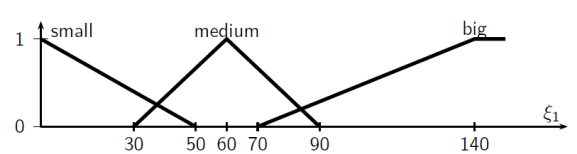

% distancia a barrera interior
fis = addMF(fis,"dis_dentro","trimf",[0 0 40],"Name","small");
fis = addMF(fis,"dis_dentro","trapmf",[20 80 150 150],"Name","big");

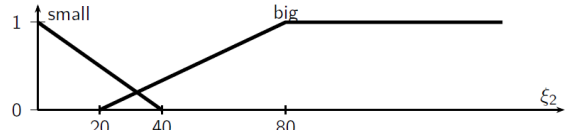

% ángulo
fis = addMF(fis,"angulo","trapmf",[-90 -90 -60 -20],"Name","outwards");
fis = addMF(fis,"angulo","trimf",[-30 0 30],"Name","forward");
fis = addMF(fis,"angulo","trapmf",[20 60 90 90],"Name","inwards");

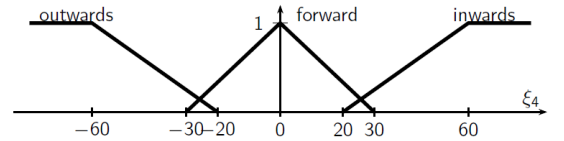

% distancia a barrera exterior
fis = addMF(fis,"dis_fuera","trimf",[0 0 40],"Name","small");

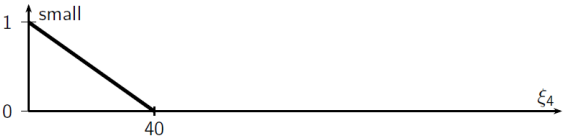

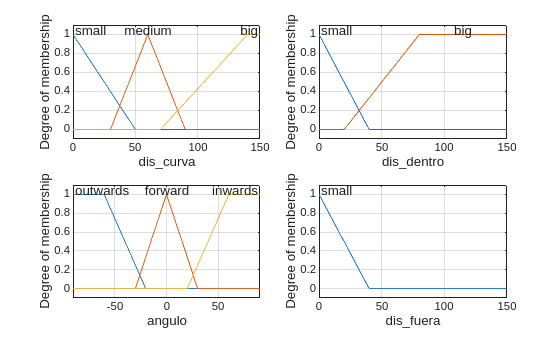

figure;
subplot(2,2,1)
plotmf(fis,"input",1);
grid on;
subplot(2,2,2)
plotmf(fis,"input",2);
grid on;
subplot(2,2,3)
plotmf(fis,"input",3);
grid on;
subplot(2,2,4)
plotmf(fis,"input",4);
grid on;

Funciones de Salida

fis = addOutput(fis,[-5 10],"Name","eta");  % rango estimado por la figura

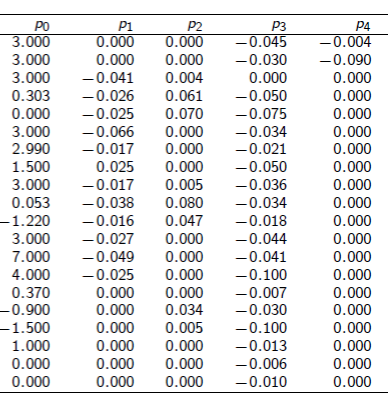

P = [
  3.000  0.000  0.000 -0.045 -0.004
  3.000  0.000  0.000 -0.030 -0.090
  3.000 -0.041  0.004  0.000  0.000
  0.303 -0.026  0.061 -0.050  0.000
  0.000 -0.025  0.070 -0.075  0.000
  3.000 -0.066  0.000 -0.034  0.000
  2.990 -0.017  0.000 -0.021  0.000
  1.500  0.025  0.000 -0.050  0.000
  3.000 -0.017  0.005 -0.036  0.000
  0.053 -0.038  0.080 -0.034  0.000
 -1.220 -0.016  0.047 -0.018  0.000
  3.000 -0.027  0.000 -0.044  0.000
  7.000 -0.049  0.000 -0.041  0.000
  4.000 -0.025  0.000 -0.100  0.000
  0.370  0.000  0.000 -0.007  0.000
 -0.900  0.000  0.034 -0.030  0.000
 -1.500  0.000  0.005 -0.100  0.000
  1.000  0.000  0.000 -0.013  0.000
  0.000  0.000  0.000  0.006  0.000
  0.000  0.000  0.000 -0.010  0.000
];

% Crear 20 MFs de salida
for i = 1:20

    p0 = P(i,1);
    p1=P(i,2);
    p2=P(i,3);
    p3=P(i,4);
    p4=P(i,5);

    fis = addMF(fis,"eta","linear",[p1 p2 p3 p4 p0],"Name",sprintf("R%d",i));
end

Reglas

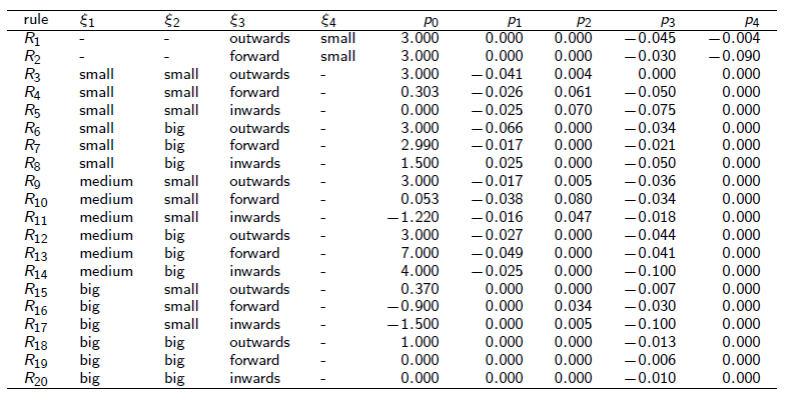

% Cada fila de "ruleList" es: f_in_1, f_in_2, f_in_3, f_in_4, f_out, weight, AND/OR
% dis_curva (f_in_1) = small, medium, big
% dis_dentro (f_in_2) = small, big
% angulo (f_in_3) = outwards, forward, inwards
% dis_fuera (f_in_4) = small
ruleList = [
              0 0 1 1  1  1 1   % R1
              0 0 2 1  2  1 1   % R2
              1 1 1 0  3  1 1   % R3
              1 1 2 0  4  1 1   % R4
              1 1 3 0  5  1 1   % R5
              1 2 1 0  6  1 1   % R6
              1 2 2 0  7  1 1   % R7
              1 2 3 0  8  1 1   % R8
              2 1 1 0  9  1 1   % R9
              2 1 2 0  10  1 1  % R10
              2 1 3 0  11  1 1  % R11
              2 2 1 0  12  1 1  % R12
              2 2 2 0  13  1 1  % R13
              2 2 3 0  14  1 1  % R14
              3 1 1 0  15  1 1  % R15
              3 1 2 0  16  1 1  % R16
              3 1 3 0  17  1 1  % R17
              3 2 1 0  18  1 1  % R18
              3 2 2 0  19  1 1  % R19
              3 2 3 0  20  1 1  % R20
          ];

fis = addRule(fis,ruleList);

Reglas Activadas

x = [10 30 0 50];

% fuzzyLogicDesigner(fis)

eta = evalfis(fis, x)

eta = 2.2518

Valores de las Funciones de Pertenencia

x = [10 30 0 50];

% grados de pertenencia de cada input a sus MFs
for k = 1:4
    in = fis.Inputs(k);
    fprintf("\n%s:\n", in.Name);
    for m = 1:numel(in.MembershipFunctions)
        mf = in.MembershipFunctions(m);
        mu = evalmf(mf, x(k));
        fprintf("  mu(%s)=%.4f\n", mf.Name, mu);
    end
end


dis_curva:


  mu(small)=0.8000
  mu(medium)=0.0000
  mu(big)=0.0000



dis_dentro:


  mu(small)=0.2500
  mu(big)=0.1667



angulo:


  mu(outwards)=0.0000
  mu(forward)=1.0000
  mu(inwards)=0.0000



dis_fuera:


  mu(small)=0.0000


Velocidad de Rotación Aplicada

eta = evalfis(fis, x)

eta = 2.2518

Distintas Configuraciones

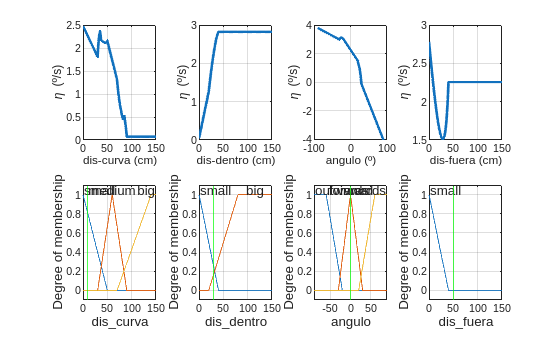

x = [10 30 0 50];

xi1 = linspace(0,150,301);
eta1 = zeros(size(xi1));
for i=1:numel(xi1)
    eta1(i) = evalfis(fis,[xi1(i) x(2) x(3) x(4)]);
end

xi2 = linspace(0,150,301);
eta2 = zeros(size(xi2));
for i=1:numel(xi2)
    eta2(i) = evalfis(fis,[x(1) xi2(i) x(3) x(4)]);
end

xi3 = linspace(-90,90,361);
eta3 = zeros(size(xi3));
for i=1:numel(xi3)
    eta3(i) = evalfis(fis,[x(1) x(2) xi3(i) x(4)]);
end

xi4 = linspace(0,150,301);
eta4 = zeros(size(xi4));
for i=1:numel(xi4)
    eta4(i) = evalfis(fis,[x(1) x(2) x(3) xi4(i)]);
end





figure;

subplot(2,4,1)
plot(xi1,eta1,"LineWidth",2);
grid on;
xlabel("dis-curva (cm)");
ylabel("\eta (º/s)");

subplot(2,4,2)
plot(xi2,eta2,"LineWidth",2);
grid on;
xlabel("dis-dentro (cm)");
ylabel("\eta (º/s)");

subplot(2,4,3)
plot(xi3,eta3,"LineWidth",2);
grid on;
xlabel("angulo (º)");
ylabel("\eta (º/s)");

subplot(2,4,4)
plot(xi4,eta4,"LineWidth",2);
grid on;
xlabel("dis-fuera (cm)");
ylabel("\eta (º/s)");

subplot(2,4,5)
plotmf(fis,"input",1);
hold on
xline(x(1),'g')
hold off
grid on;
subplot(2,4,6)
plotmf(fis,"input",2);
hold on
xline(x(2),'g')
hold off
grid on;
subplot(2,4,7)
plotmf(fis,"input",3);
hold on
xline(x(3),'g')
hold off
grid on;
subplot(2,4,8)
plotmf(fis,"input",4);
hold on
xline(x(4),'g')
hold off
grid on;